# Homework 2 - ECE4560

Brett Erickson

use_pkg_here('robotics'); %Helper function written by ChatGPT, for file location resolution only.
import robotics.*

**1.    4 hours **- primarily spent troubleshooting my package

**2.   ** 

a)

l1 = 4;
l2 = 2;

theta_1 = pi/4;
theta_2 = pi/2;

b.x = l1 * cos(-theta_1);
b.y = l1 * -sin(-theta_1);
b.theta = -theta_1 + -theta_2;

e.x = b.x + -l2*cos(-b.theta);
e.y = b.y + l2*sin(b.theta);
e.theta = b.theta;

fprintf("Effector configuration is g_we = ([%.2f, %.2f], R(%.2f rad)",e.x,e.y,e.theta);

Effector configuration is g_we = ([4.24, 1.41], R(-2.36 rad)

b)

g_wa = transform2d([0; 0], -theta_1);
g_ab = transform2d([0; l1], -theta_2);
g_be = transform2d([0; l2], 0);

g_we = compose(compose(g_wa,g_ab),g_be);
fprintf("Effector configuration is g_we = ([%.2f, %.2f], R(%.2f rad)",g_we.displacement(1),g_we.displacement(2),g_we.theta);

Effector configuration is g_we = ([4.24, 1.41], R(-2.36 rad)

3.

function outMat = homogeneousMatrix(x,y,theta)
    outMat = [cos(theta) -sin(theta) x; sin(theta) cos(theta) y; 0 0 1];
end

function outMat = homogeneousInverse(outMat)
    rotation_transpose = transpose(outMat(1:2,1:2));
    outMat = [rotation_transpose, -rotation_transpose*outMat(1:2,3); 0 0 1];
end

bbprime = homogeneousMatrix(10,1,-pi/4);
h = homogeneousMatrix(0.1,1,-pi/8);
h_inverse = homogeneousInverse(h);

ccprime = h*bbprime*h_inverse;
fprintf("Transform CC' = ([%.2f, %.2f], R(%.2f rad)",ccprime(1,3),ccprime(2,3),atan2(ccprime(2,1),ccprime(1,1)));

Transform CC' = ([8.94, -2.54], R(-0.79 rad)

4.

g_wr = homogeneousMatrix(2,3,pi/4);
g_ro = homogeneousMatrix(3,1,-pi/3);
g_wo = g_wr*g_ro;
fprintf("Object with respect to worldframe = ([%.2f, %.2f], R(%.2f rad)",g_wo(1,3),g_wo(2,3),atan2(g_wo(2,1),g_wo(1,1)));

Object with respect to worldframe = ([3.41, 5.83], R(-0.26 rad)

5.

Since I built my own SO-101 arm (named Jack the Gripper, henceforth refered to as Jack), I had to do all of the steps from construction to motor identification. 

I started off by attempting to work with conda, but I couldn't get it to work and didn't want to maintain a virtual environment from the command line. So instead I created a github repo and installed uv (the package and environment manager), then began the installation of lerobot and its dependencies. My intention was to make the repo a one-shot solution for other students to pull and code with the SO-101. 

It does work, and I hope that in the future my team will work within that repo to collaborate on code, ensuring we all are operating on common dependencies and a standardized virtual envirionment. 

[https://github.com/berickon3/ECE-4560_Lab.git](https://github.com/berickon3/ECE-4560_Lab.git)

Once that was done, I did the motor ID, calibrated the arm, calibrated a follower from the lab, then performed the teleoperation. I noted that even a small discrepancy in the calibration (not going to the full extention of a joint) would cause that joint to have a ratio of movement to the leader not 1:1.

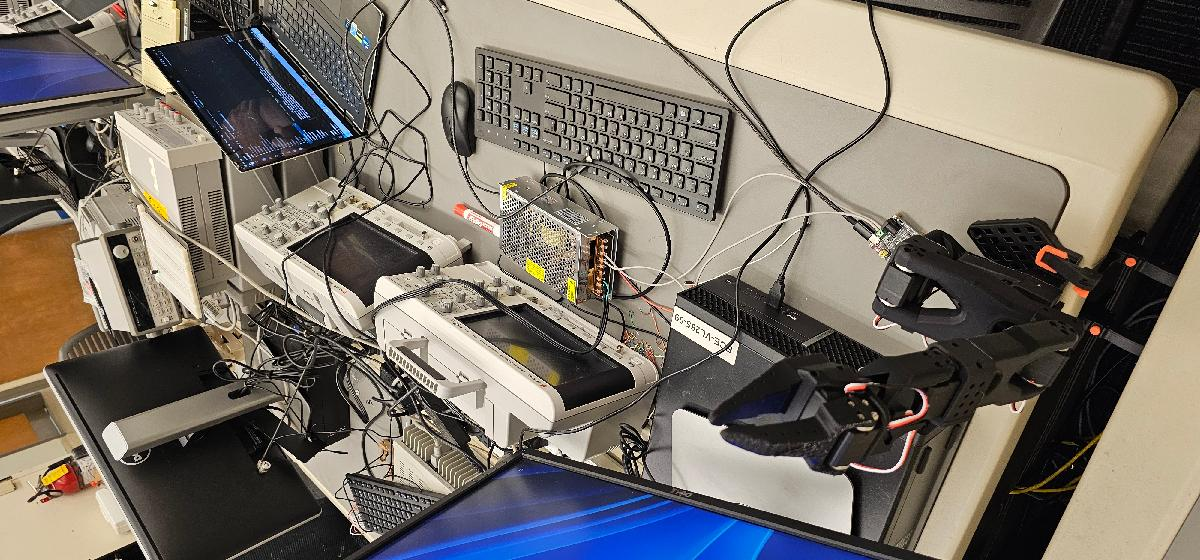

#### APPENDIX A:

This code was generated by ChatGPT. I got very tired of working to resolve relative and absolute filepaths to find my robotics package, where each homework.mlx has its own folder. The complication is that I want this repo to be available to pull and run anywhere, agnostic of file install location. 'import' no longer suports relative filepaths, so thats out. 

I'm tired, boss.

function use_pkg_here(pkg)
% Make the parent of the current live script the CWD temporarily so +pkg is visible.
% Robust against Live Editor's temp execution folder.

    % Resolve the source file of the active Live Script
    src = "";
    try
        src = string(matlab.desktop.editor.getActiveFilename);
    catch
    end
    if src=="" || ~isfile(src)
        st = dbstack('-completenames');
        if ~isempty(st), src = string(st(end).file); end
    end
    assert(src~="" && isfile(src), 'Unable to resolve the source .mlx path.');

    % Repo root is the parent of the folder containing this .mlx
    %   .../Robotics-Code/homework2/homework_2.mlx
    % -> .../Robotics-Code
    thisDir   = fileparts(src);
    repoRoot  = fileparts(thisDir);

    % Verify +pkg exists at repo root
    pkgDir = fullfile(repoRoot, ['+' char(pkg)]);
    assert(isfolder(pkgDir), 'Expected package folder not found: %s', pkgDir);

    % Temporarily cd into repo root so +pkg is discoverable; auto-restore
    orig = pwd;
    cleaner = onCleanup(@() cd(orig));
    cd(repoRoot);

    % Nothing else to do here; the caller can now 'import pkg.*'
end